# FigureDeployer

Class used to deploy figures as images or byte streams.

This class is primarily meant to be used in a [MATLAB Production Server](https://www.mathworks.com/products/matlab-production-server.html) to return image data to a client.  It can be useful for any image deployment needs, however!

## Methods

### FigureDeployer Constructor

Usage:

- `fd = FigureDeployer`

- `fd = FigureDeployer(Name=value, ...)`

Any of the properties are valid name-value pairs.

### getImage

Get the output image.

Usage:

- `[imdata, imname] = getImage(fd)`

Outputs:

- `imdata `is the matrix of values.

- `imname` is the name of the image on disk.

### **getStream**

Get byte or char stream output

Usage:

- `stream = getStream(fd)`

Outputs:

- `stream`: Byte stream of class uint8 for raster images with *'OutputType'* set to *'uint8'*, It will be a character stream for svg or *'OutputType'* set to *'base64'*. 

## Properties

### Figure

Handle to figure to deploy.  Default is `get(groot, 'CurrentFigure')`.  This will not create a new figure if none exist.

### Height

Numeric scalar.  Height of output in pixels.  Default 450.

### Width

Numeric Scalar.  Width of output in pixels.  Default 600.

### ImageName

Image name to generate.  Default is a `tempname`.

### ImageType

Image type to generate.  Available options:

{['png'], 'jpg', 'svg', 'gif'}

### Resolution

Numeric scalar.  Dots per inch for output figure.  Default is 150.  Not used by *svg* *ImageType*.

### OutputType

Output type of non-SVG image stream.  Available options:

{['uint8'], "base64"}

SVG is always a character vector output type.

## Examples

### Example 1: Deploy Figure as an Image

This example generates an image file.

Make example figure:

f = figure;
surf(peaks)
xlabel("This is X")
ylabel("I'm Y")

Deploy it to png.

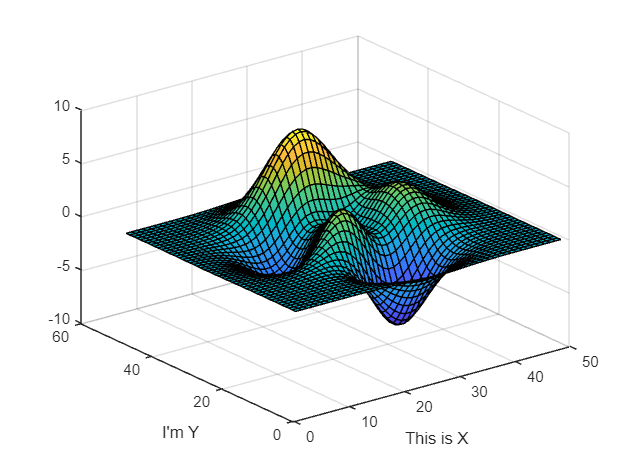

DF = FigureDeployer(Figure=f, ImageType='png', ImageName='example', Width=500, Height=500);
[imdata, imname] = getImage(DF);

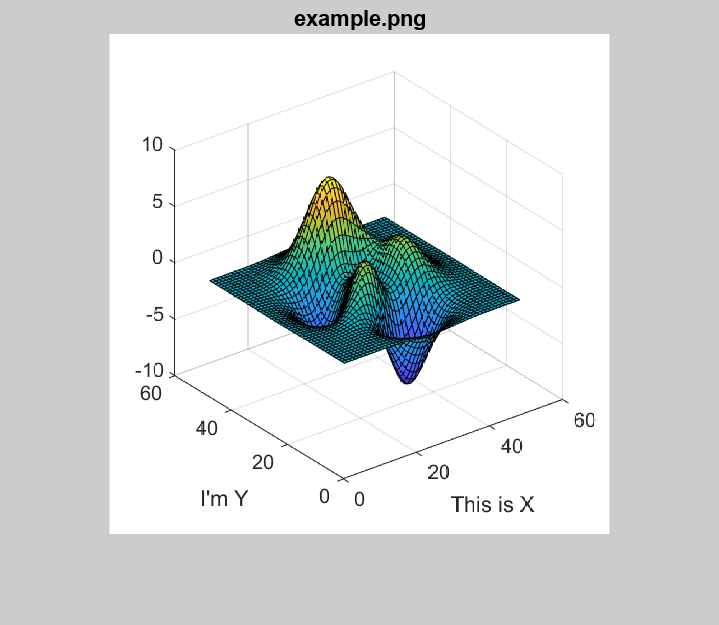

deleter = onCleanup(@()delete(imname));
figure(Color=[0.8 0.8 0.8])
imshow(imdata)
title(imname)

### Example 2: Deploy Bytestream to Web Page

This example deploys a bytestream to base64 which is then binded to an <img> in HTML.

Make example image:

f = figure;
surf(peaks)
xlabel("This is X")
ylabel("I'm Y")

Deploy as base64.

DF = FigureDeployer(Figure=f, ImageType='png', ImageName='example', Width=500, Height=500, OutputType="base64");
imstream = getStream(DF);

Define HTML <img> with base64 source.

htmltemplate = '<html><body><img src="data:image/png;base64,%s" height="500" width="500"></body></html>';
html = sprintf(htmltemplate, imstream);

Show it.

f = uifigure;
f.Position(3:4) = 600;
h = uihtml(f, HTMLSource=html, Position=[50 50 500 500]);

This is the resulting uifigure.

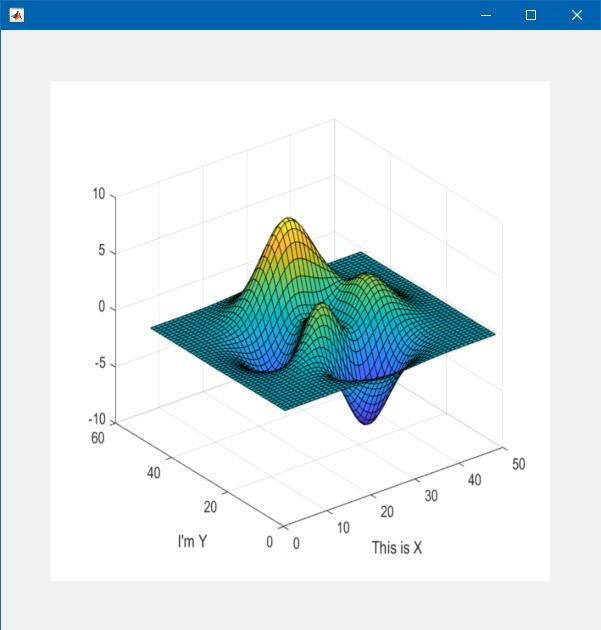

## Limitations

- SVG is not supported for figures created with the `uifigure` function.

*Copyright 2020 The MathWorks, Inc.*